Importar imagens

ifsp2005 = imread("2005.png");
ifsp2011 = imread("2011.png");
ifsp2019 = imread("2019.png");
ifsp2021 = imread("2021.png");
%escalaIFSP = imread("escalaKM.png");

Comparativo das imagens

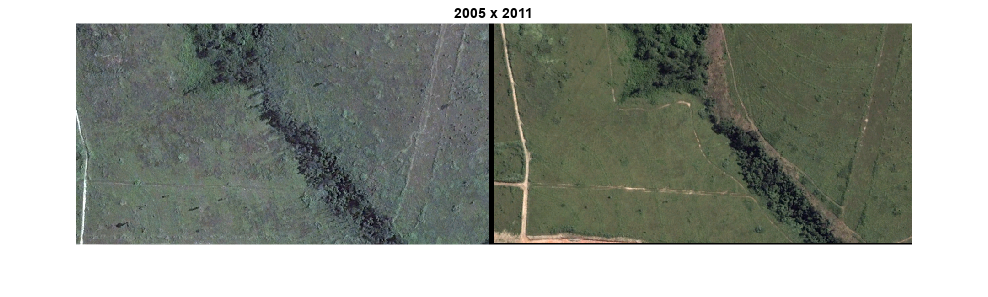

imshowpair(ifsp2005, ifsp2011, "montage")
title("2005 x 2011")

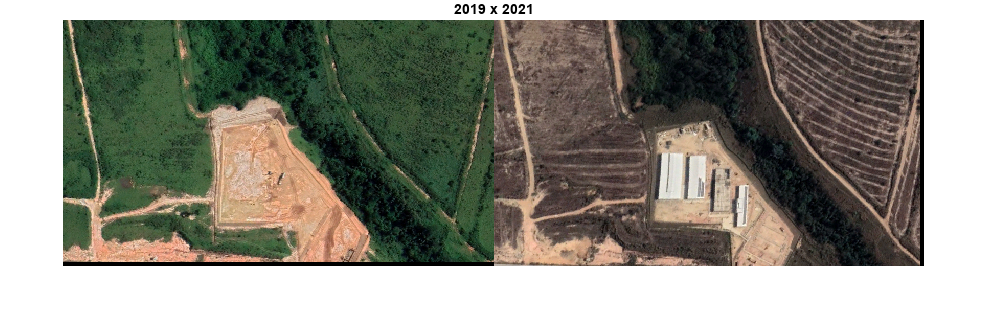

imshowpair(ifsp2019, ifsp2021, "montage")
title("2019 x 2021")

Imagem em cinza para melhor aplicação da mascara "thresholding"

grayIFSP2005 = im2gray(ifsp2005)

grayIFSP2005 = 483×902 uint8 matrix
    81    68    57    50    58    40    50    70    78    76    73    87    90    82    81    83    90    89    77    67    64    65    87   100    95    96    87    75    76    78    84   100   106    93    89    99   107   107   103   110   117   109    90    73    93    97   100   105   105    99
    77    73    64    65    71    61    49    58    59    64    71    89    90    76    64    77    83    87    89    83    83    89    97   100    95    93    87    81    77    78    86    95   100   104   105   102   102   113   120   115   110    99    85    84    89    93   106   106   102    98
    81    80    87    86    79    73    68    61    66    74    76    79    89    79    76    71    70    80    96   105    95    87    97   103    99    95    95    89    85    85    95   102   112   119   123   114   124   131   130   121   103   104   105   100    81    86   101   110   111   107
    94    91    98    90    79    78    78    80    78    81 

grayIFSP2011 = im2gray(ifsp2011)

grayIFSP2011 = 479×914 uint8 matrix
    93    90    87    84    88    89    84    74    79    89    94    91    91   115   141   175   214   207   207   156    81    66    65    76   102   116   120   115   109   106   103    99   100   109   114   116   117   109   103   104    99    95   100   107   111   111   110   115   118   119
    98    98    86    80    78    78    83    83    80    88    98    97    92    92   137   174   207   209   209   157   108    70    66    74    87   101   108   103   100   106   106   104   104   106   109   108   106   105   108   111   107   105   106   113   116   119   117   116   115   107
    93    94    87    80    74    74    80    83    82    82    93   101    98    93   123   157   199   213   207   172   131    66    66    66    73    95   109   104    98    97   102   103   103   103   100   102    99   103   109   113   111   111   116   116   119   124   122   117   111   105
    92    95    93    83    77    79    81    80    78    82 

grayIFSP2019 = im2gray(ifsp2019)

grayIFSP2019 = 473×842 uint8 matrix
    54    59    65    60    63    67    74    74    99   131   180   203   204   203   173   102    55    53    37    52    53    51    47    41    41    42    54    53    52    59    63    68    65    61    61    58    63    72    74    56    46    38    24    31    57    48    43    39    49    59
    53    57    59    58    62    67    83    79    99   127   175   204   203   203   171   114    45    44    43    51    59    54    44    31    23    37    55    57    53    54    54    59    65    64    65    62    54    65    62    64    56    50    28    16    15    35    42    42    49    55
    42    47    54    62    69    71    80    80    80   118   175   207   203   203   187   151   107    58    55    59    61    61    53    39    23    26    40    51    55    47    48    53    54    53    61    63    60    63    58    64    64    59    50    30    14    30    36    37    42    74
    20    29    47    63    76    74    82    80    82   116 

grayIFSP2021 = im2gray(ifsp2021)

grayIFSP2021 = 481×835 uint8 matrix
   102   102   106   106   103    95    94    86    94   117   123   127   148   167   176   180   183   180   171   170   140   114    83    67    75    64    55    52    60    57    64    65    75    81    98   114   126   128   133   129   131   126   124   116   106   102   105   104    99    90
   100    99    95    97    96    95    95    90    94   116   127   138   147   161   175   180   184   185   179   170   149   123    86    69    72    71    68    68    72    70    80    84    87    96   112   127   131   131   133   126   118   109   117   117   102    99   100   100    95    95
    91    84    82    84    87    97   109   104    96   112   127   121   146   161   176   184   188   184   175   167   146   121   105    70    67    77    81    77    62    69    78    78    85   105   125   133   134   132   132   123   104   109   112   115   102    94    90    91    91    90
    80    76    78    80    85   100   116   114   108   108 

Realçar as imagens em cinza

adj2005 = imadjust(grayIFSP2005)

adj2005 = 483×902 uint8 matrix
   114    81    53    35    56    10    35    86   106   101    93   129   136   116   114   119   136   134   104    78    71    73   129   162   149   151   129    98   101   106   121   162   177   144   134   159   179   179   169   187   205   184   136    93   144   154   162   174   174   159
   104    93    71    73    88    63    33    56    58    71    88   134   136   101    71   104   119   129   134   119   119   134   154   162   149   144   129   114   104   106   126   149   162   172   174   167   167   194   212   199   187   159   124   121   134   144   177   177   167   157
   114   111   129   126   109    93    81    63    76    96   101   109   134   109   101    88    86   111   151   174   149   129   154   169   159   149   149   134   124   124   149   167   192   210   220   197   222   240   237   215   169   172   174   162   114   126   164   187   189   179
   146   139   157   136   109   106   106   111   106   114   109

adj2011 = imadjust(grayIFSP2011)

adj2011 = 479×914 uint8 matrix
   123   118   113   108   115   116   108    91    99   116   125   120   120   161   205   255   255   255   255   231   103    77    75    94   139   163   169   161   151   145   140   133   135   151   159   163   164   151   140   142   133   127   135   147   154   154   152   161   166   168
   132   132   111   101    98    98   106   106   101   115   132   130   122   122   199   255   255   255   255   233   149    84    77    91   113   137   149   140   135   145   145   142   142   145   151   149   145   144   149   154   147   144   145   157   163   168   164   163   161   147
   123   125   113   101    91    91   101   106   104   104   123   137   132   123   175   233   255   255   255   255   188    77    77    77    89   127   151   142   132   130   139   140   140   140   135   139   133   140   151   157   154   154   163   163   168   176   173   164   154   144
   122   127   123   106    96    99   103   101    98   104   118

adj2019 = imadjust(grayIFSP2019)

adj2019 = 473×842 uint8 matrix
    63    70    77    71    75    80    89    89   121   161   223   252   254   252   214   124    65    62    42    61    62    60    55    47    47    48    63    62    61    70    75    81    77    72    72    69    75    86    89    66    53    43    25    34    67    56    49    44    57    70
    62    67    70    69    74    80   100    95   121   156   217   254   252   252   212   140    52    51    49    60    70    63    51    34    24    42    65    67    62    63    63    70    77    76    77    74    63    77    74    76    66    58    30    15    14    39    48    48    57    65
    48    55    63    74    82    85    96    96    96   145   217   255   252   252   232   186   131    69    65    70    72    72    62    44    24    28    46    60    65    55    56    62    63    62    72    75    71    75    69    76    76    70    58    33    13    33    41    42    48    89
    20    32    55    75    91    89    99    96    99   142   199

adj2021 = imadjust(grayIFSP2021)

adj2021 = 481×835 uint8 matrix
   114   114   119   119   115   106   105    95   105   132   139   143   168   190   200   205   208   205   194   193   158   128    92    73    83    70    59    56    65    62    70    71    83    90   109   128   142   144   150   146   148   142   140   130   119   114   118   116   111   100
   112   111   106   108   107   106   106   100   105   130   143   156   167   183   199   205   210   211   204   193   169   139    95    76    79    78    75    75    79    77    88    93    97   107   126   143   148   148   150   142   133   122   132   132   114   111   112   112   106   106
   101    93    91    93    97   108   122   116   107   126   143   136   165   183   200   210   214   210   199   190   165   136   118    77    73    85    90    85    68    76    86    86    94   118   141   150   151   149   149   139   116   122   126   129   114   105   100   101   101   100
    88    84    86    88    94   112   130   128   121   121   134

Imagem realçada e com mascara "thresholding"

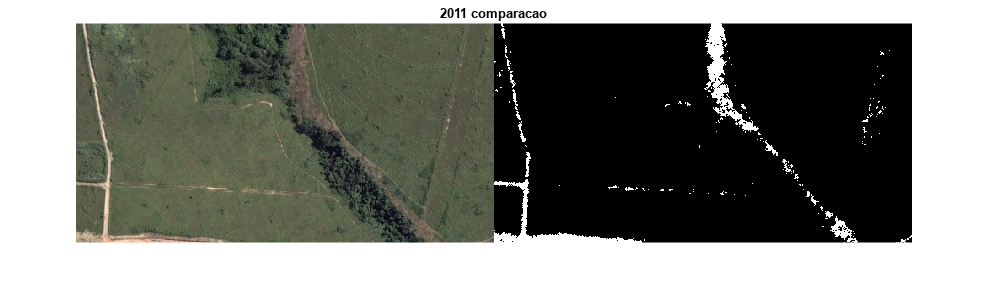

ms2011 = ifspMask(ifsp2011);
imshowpair(ifsp2011, ms2011, "montage")
title("2011 comparacao")

Aplicação das variaveis que faltaram

ms2005 = ifspMask(ifsp2005);
ms2019 = ifspMask(ifsp2019);
ms2021 = ifspMask(ifsp2021);

Calculando a area em pixels pt1

props = regionprops("table", ms2011, "Area")

props = 240×1 table
    Area
    ____

      18
    6361
       4
      17
       4
       1
       1
      29
      10
     152
      11
      60
       2
      30
      74
      21


areaPixels = sum(props.Area)

areaPixels = 18693

Calculando a area em pixels pt2

px2km = (666/0.50)^2

px2km = 1774224

areaKmSq = round(areaPixels*px2km)

areaKmSq = 3.3166e+10

Percentual de desmatamento

%total de mata virgem%
100 - (allresults.areaKmSq(1,1)+allresults.areaKmSq(2,1)+allresults.areaKmSq(3,1)+allresults.areaKmSq(4,1))/768573198611*100

ans = 3.1895

%Porcentagem de desmatamento 2005
allresults.areaKmSq(1,1)/768573198611 * 100

ans = 0.2624

%Porcentagem de desmatamento 2011
allresults.areaKmSq(2,1)/768573198611 * 100

ans = 4.6542

%Porcentagem de desmatamento 2019
allresults.areaKmSq(3,1)/768573198611*100

ans = 20.8431

%porcentagem de desmatamento 2021
allresults.areaKmSq(4,1)/768573198611 * 100

ans = 71.0508

Area em grafico de barras

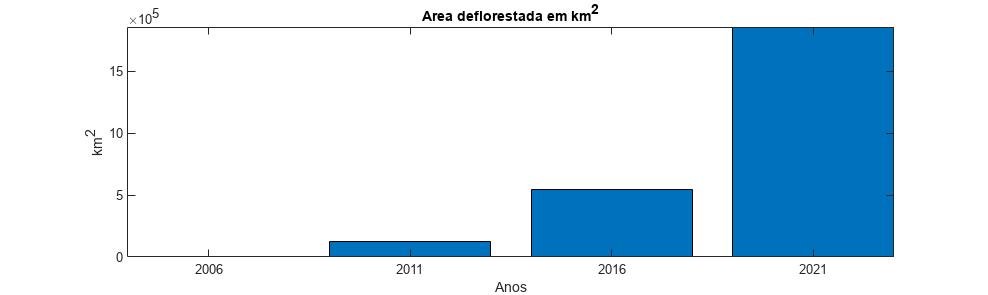

nYears = 2006:5:2021;
areas = allresults.areaKmSq;
bar(nYears,areas)
title("Area deflorestada em km^{2}")
xlabel("Anos")
ylabel("km^{2}")
axis tight